clear all;   % This clears all workspaces
close all;   % This closes all figures 
clc;         % This clears the command window
format long; 

name = 'Neo Lee';
id = 'A17050803';
hw_num = 4;

%% Problem 1: 
A = [log(1/2) log(1/3) log(1/4) log(1/5);
    log(1/6) log(1/7) log(1/8) log(1/9);
    log(1/10) log(1/11) log(1/12) log(1/13)]

A =   -0.693147180559945  -1.098612288668110  -1.386294361119891  -1.609437912434100
  -1.791759469228055  -1.945910149055313  -2.079441541679836  -2.197224577336220
  -2.302585092994045  -2.397895272798371  -2.484906649788000  -2.564949357461537


% (a)
p1a = sprintf('%9.6f\n', A(:,4))

p1a =     '-1.609438
     -2.197225
     -2.564949
     '



% (b)
p1b = sprintf('%7.4f ', A(3,:))

p1b = '-2.3026 -2.3979 -2.4849 -2.5649 '


% (c)
p1c = sprintf('%10.7f %10.7f %10.7f %10.7f\n', A')

p1c =     '-0.6931472 -1.0986123 -1.3862944 -1.6094379
     -1.7917595 -1.9459101 -2.0794415 -2.1972246
     -2.3025851 -2.3978953 -2.4849066 -2.5649494
     '



% (d)
p1d = sprintf('%10.7e %10.7e %10.7e %10.7e\n', A')

p1d =     '-6.9314718e-01 -1.0986123e+00 -1.3862944e+00 -1.6094379e+00
     -1.7917595e+00 -1.9459101e+00 -2.0794415e+00 -2.1972246e+00
     -2.3025851e+00 -2.3978953e+00 -2.4849066e+00 -2.5649494e+00
     '



%% Problem 2
temp = load('temperature.dat')

temp = 1.0e+03 *

   1.852000000000000   0.053100000000000   0.055900000000000   0.055000000000000   0.057600000000000   0.061200000000000   0.067100000000000   0.073200000000000   0.072500000000000   0.073600000000000   0.064900000000000   0.057400000000000   0.057900000000000
   1.853000000000000   0.053800000000000   0.053100000000000   0.057700000000000   0.062600000000000   0.063300000000000   0.068400000000000   0.072900000000000   0.072900000000000   0.070700000000000   0.068700000000000   0.060400000000000   0.056100000000000
   1.854000000000000   0.054100000000000   0.055000000000000   0.056500000000000   0.063300000000000   0.060600000000000   0.064000000000000   0.073000000000000   0.072100000000000   0.066700000000000   0.064000000000000   0.058600000000000   0.055600000000000
   1.855000000000000   0.052500000000000   0.056100000000000   0.058500000000000   0.062200000000000   0.064000000000000   0.068700000000000   0.070900000000000   0.072000000000000   0.06840000000000

temp_only = temp(:,2:13)

temp_only =   53.100000000000001  55.899999999999999  55.000000000000000  57.600000000000001  61.200000000000003  67.099999999999994  73.200000000000003  72.500000000000000  73.599999999999994  64.900000000000006  57.399999999999999  57.899999999999999
  53.799999999999997  53.100000000000001  57.700000000000003  62.600000000000001  63.299999999999997  68.400000000000006  72.900000000000006  72.900000000000006  70.700000000000003  68.700000000000003  60.399999999999999  56.100000000000001
  54.100000000000001  55.000000000000000  56.500000000000000  63.299999999999997  60.600000000000001  64.000000000000000  73.000000000000000  72.099999999999994  66.700000000000003  64.000000000000000  58.600000000000001  55.600000000000001
  52.500000000000000  56.100000000000001  58.500000000000000  62.200000000000003  64.000000000000000  68.700000000000003  70.900000000000006  72.000000000000000  68.400000000000006  66.599999999999994  56.500000000000000  52.299999999999997
  51.100000000000001  53

% (a) & (b)
[a, b] = find(temp_only == max(temp_only(:)))

a =    133


b =      9


p2a = b

p2a =      9


p2b = a + 1851

p2b =         1984



% (c)
p2c = sum(temp_only(find(temp == 1900):find(temp == 2000),:) > 75, 'all')

p2c =     11



% (d)
p2d = sum(temp_only(find(temp == 1900):find(temp == 2000),6:8) > 75, 'all')

p2d =      7



% (e)
average_temp = mean(temp_only)

average_temp =   55.580059171597640  56.551952662721909  58.230236686390533  60.445029585798821  62.693727810650884  65.469940828402372  69.095384615384603  70.587159763313608  69.042248520710061  65.350118343195263  60.584497041420114  56.580591715976325


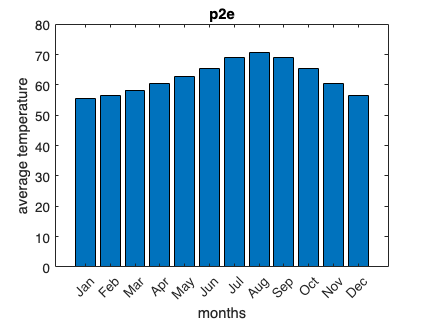

figure(1)
bar(average_temp)
xlabel('months')
ylabel('average temperature')
title('p2e')

p2e = 'See figure 1'

p2e = 'See figure 1'


% (f)
p2f = 'In general, the temperature peaks in August'

p2f = 'In general, the temperature peaks in August'


% (g)
temp_cycle = [1:12; average_temp]'

temp_cycle =    1.000000000000000  55.580059171597640
   2.000000000000000  56.551952662721909
   3.000000000000000  58.230236686390533
   4.000000000000000  60.445029585798821
   5.000000000000000  62.693727810650884
   6.000000000000000  65.469940828402372
   7.000000000000000  69.095384615384603
   8.000000000000000  70.587159763313608
   9.000000000000000  69.042248520710061
  10.000000000000000  65.350118343195263


save('annual_cycle.dat', 'temp_cycle', '-ascii')
p2g= evalc('type(''annual_cycle.dat'')')

p2g =     '
        1.0000000e+00   5.5580059e+01
        2.0000000e+00   5.6551953e+01
        3.0000000e+00   5.8230237e+01
        4.0000000e+00   6.0445030e+01
        5.0000000e+00   6.2693728e+01
        6.0000000e+00   6.5469941e+01
        7.0000000e+00   6.9095385e+01
        8.0000000e+00   7.0587160e+01
        9.0000000e+00   6.9042249e+01
        1.0000000e+01   6.5350118e+01
        1.1000000e+01   6.0584497e+01
        1.2000000e+01   5.6580592e+01
     '



% (h)
annual_mean_temp = mean(temp_only')

annual_mean_temp =   62.449999999999989  63.383333333333333  61.958333333333343  62.391666666666659  60.941666666666670  62.350000000000001  61.591666666666676  61.058333333333344  61.291666666666664  63.316666666666684  62.474999999999987  61.625000000000000  63.400000000000006  62.050000000000004  62.941666666666663  63.791666666666657  62.183333333333337  63.050000000000004  61.208333333333336  61.791666666666657  60.358333333333327  60.575000000000010  59.508333333333333  61.558333333333337  60.950000000000010  62.016666666666659  60.549999999999990  60.000000000000000  58.416666666666679  60.383333333333333  59.774999999999999  61.133333333333333  60.625000000000007  62.149999999999984  60.416666666666657  60.508333333333326  61.483333333333327  62.233333333333327  61.475000000000001  60.875000000000000  59.949999999999996  60.316666666666670  58.141666666666673  60.208333333333321  61.599999999999994  60.624999999999993  60.216666666666661  59.841666666666661  61.716666666666669 

figure(2)
hold on
plot(1852:2020,annual_mean_temp, '-k', 'LineWidth', 2)
plot(find(annual_mean_temp > 65) + 1851, annual_mean_temp(annual_mean_temp > 65), 'ro', 'MarkerFaceColor', 'r')
plot(find(annual_mean_temp < 60) + 1851, annual_mean_temp(annual_mean_temp < 60), 'bd', 'MarkerFaceColor', 'b')
y_diff = diff(annual_mean_temp)

y_diff =    0.933333333333344  -1.424999999999990   0.433333333333316  -1.449999999999989   1.408333333333331  -0.758333333333326  -0.533333333333331   0.233333333333320   2.025000000000020  -0.841666666666697  -0.849999999999987   1.775000000000006  -1.350000000000001   0.891666666666659   0.849999999999994  -1.608333333333320   0.866666666666667  -1.841666666666669   0.583333333333321  -1.433333333333330   0.216666666666683  -1.066666666666677   2.050000000000004  -0.608333333333327   1.066666666666649  -1.466666666666669  -0.549999999999990  -1.583333333333321   1.966666666666654  -0.608333333333334   1.358333333333334  -0.508333333333326   1.524999999999977  -1.733333333333327   0.091666666666669   0.975000000000001   0.750000000000000  -0.758333333333326  -0.600000000000001  -0.925000000000004   0.366666666666674  -2.174999999999997   2.066666666666649   1.391666666666673  -0.975000000000001  -0.408333333333331  -0.375000000000000   1.875000000000007  -0.833333333333343  -1.158333

up_x1 = find(y_diff == max(y_diff))

up_x1 =     82


up_x2 = up_x1 + 1

up_x2 =     83


plot([up_x1+1851 up_x2+1851], [annual_mean_temp(up_x1) annual_mean_temp(up_x2)], '-r', 'LineWidth', 4)
down_x1 = find(y_diff == min(y_diff))

down_x1 =     80


down_x2 = down_x1 + 1

down_x2 =     81


plot([down_x1+1851 down_x2+1851], [annual_mean_temp(down_x1) annual_mean_temp(down_x2)], '-b', 'LineWidth', 4)
title('p2h')
xlabel('Year')
ylabel('Annual Mean Temperature')
legend('temp', 'temp > 65F', 'temp < 60F', 'rapid rise', 'rapid drop')

p2h = 'See figure 2'

p2h = 'See figure 2'


% (i)
p2i = 'In general, the temperature get warmer over the years'

p2i = 'In general, the temperature get warmer over the years'


%% Problem 3
p3a = evalc('help lottery')

p3a =     '  lottery function tells you how much you win
       input [a b c d e f] with the sixth integers on your ticket
     
     '


p3b = lottery([2, 3, 4, 5, 6, 7])

p3b =      0


p3c = lottery([12, 23, 24, 34, 50, 61])

p3c =        10000


p3d = lottery([22, 33, 44, 50, 51, 61])

p3d =         1000


p3e = lottery([32, 43, 54, 44, 51, 61])

p3e =         1000


p3f = lottery([42, 53, 34, 44, 51, 61])

p3f =        10000


p3g = lottery([42, 23, 34, 44, 51, 61])

p3g =      1000000


p3h = lottery([12, 23, 34, 44, 51, 61])

p3h =    100000000



%% Problem 4
p4a = evalc('help piecewise2d')

p4a =     '  piecewise2d equates differently according to different (x,y) input
       input (x,y) to use the function
     
     '


p4b = piecewise2d(1, 1)

p4b =     20


p4c = piecewise2d(1, -1)

p4c =     20


p4d = piecewise2d(-1, 1)

p4d =     20


p4e = piecewise2d(-1, -1)

p4e =     20


p4f = piecewise2d(0, 0)

p4f =      0


p4g = piecewise2d(0, 1)

p4g =     10


p4h = piecewise2d(0, -1)

p4h =     10


p4i = piecewise2d(1, 0)

p4i =     10


p4j = piecewise2d(-1, 0)

p4j =     10



%% Problem 5
p5a = evalc('help rgb_color')

p5a =     '  rgb_color tells you the final color for different rgb combination
       input [x y z] with only 0 or 1 value
     
     '


p5b = rgb_color([1 1 1])

p5b = 'white'

p5c = rgb_color([1 0 0])

p5c = 'red'

p5d = rgb_color([0 1 0])

p5d = 'green'

p5e = rgb_color([0 0 1])

p5e = 'blue'

p5f = rgb_color([1 1 0])

p5f = 'yellow'

p5g = rgb_color([0 1 1])

p5g = 'cyan'

p5h = rgb_color([1 0 1])

p5h = 'magenta'

p5i = rgb_color([0 0 0])

p5i = 'Invalid input'